clear; clc; close all;

split_percent = 0.8;
split_idx = split_percent * size(labels, 2);
X_Train = features(:, :, :, 1:split_idx);
Y_Train = labels(:, 1:split_idx);
X_Test = features(:, :, :, split_idx+1:end);
Y_Test = labels(:, split_idx+1:end);

dsTrain = MyDataStore(X_Train, Y_Train);
dsTest = MyDataStore(X_Test, Y_Test);
dsTrain, dsTest

dsTrain =   MyDataStore with properties:

    Features: [8×8×2×12640 double]
      Labels: [60×12640 double]


dsTest =   MyDataStore with properties:

    Features: [8×8×2×3160 double]
      Labels: [60×3160 double]


% Compile the model with specified loss function
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs', 500, ...
    'MiniBatchSize', 64, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 500
                   MiniBatchSize: 64
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvi

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |         3.87 |          7.5 |          0.0010 |
|       1 |          50 |       00:00:02 |         2.30 |          2.6 |          0.0010 |
|       1 |         100 |       00:00:03 |         1.49 |          1.1 |          0.0010 |
|       1 |         150 |       00:00:04 |         1.42 |          1.0 |          0.0010 |
|       2 |         200 |       00:00:05 |         1.41 |          1.0 |          0.0010 |
|       2 |         250 |       00:00:06 |         1.41 |          1.0 |          0.0010 |
|       2 |         300 |       00:00:07 |         1.41 |         

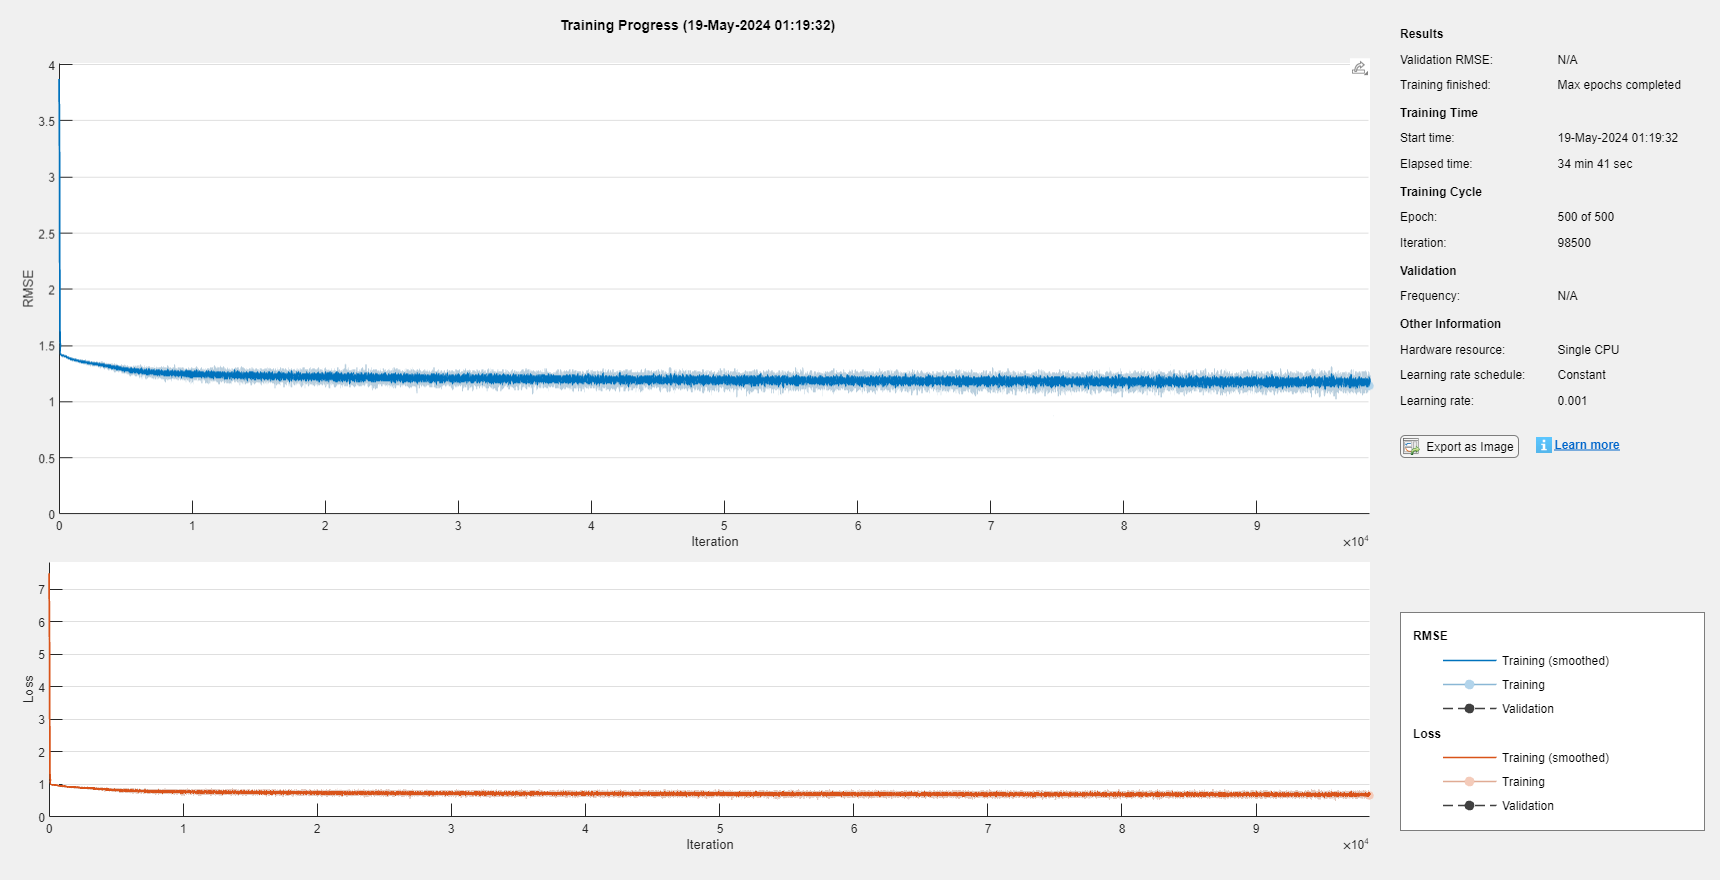

net =   DAGNetwork with properties:

         Layers: [22×1 nnet.cnn.layer.Layer]
    Connections: [21×2 table]
     InputNames: {'imageinput'  'imageinput_1'}
    OutputNames: {'regressionoutput'}


net = trainNetwork(dsTrain, lgraph, options)

a = read(dsTrain)

a = 1×3 cell array
    {8×8 double}    {8×8 double}    {60×1 double}


lgraph.InputNames

ans = 1×2 cell array
    {'imageinput3D'}    {'imageinput3D_1'}


lgraph.OutputNames

ans = 1×1 cell array
    {'regressionoutput'}


YPred = predict(net, X_Test).';
E = size(X_Test, 2);
avg_rmse = 0;
for i = 1:E
    avg_rmse = avg_rmse + rmse(YPred(:, i), Y_Test(:, i));
end
avg_rmse = avg_rmse / E

# Testing

load CM.mat
addpath('D:\D\Alp\Master ODTÜ\Thesis\DOA\Codes\Direction-of-Arrival');
DOA = FunctionsOfDOA();

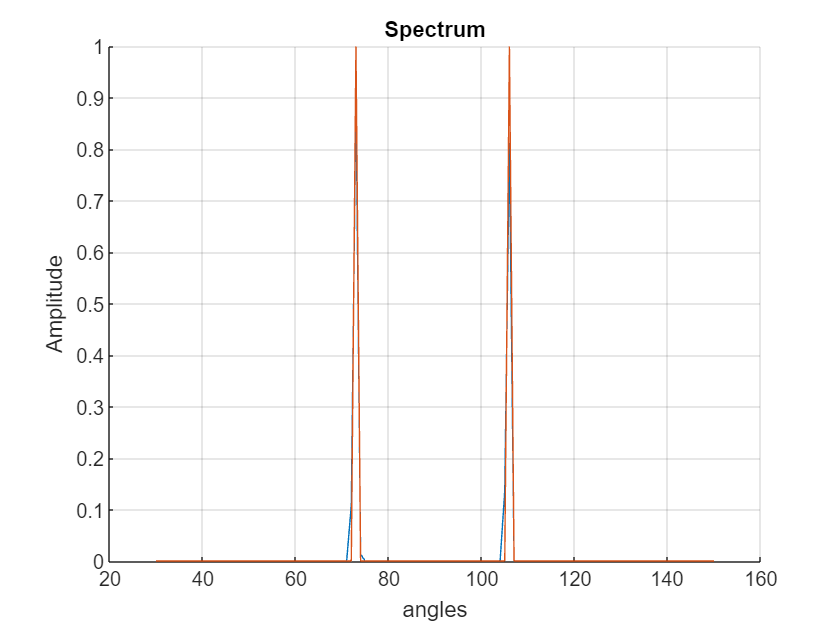

actual doa angles = 72.775 105.7113


Test(DOA, net);

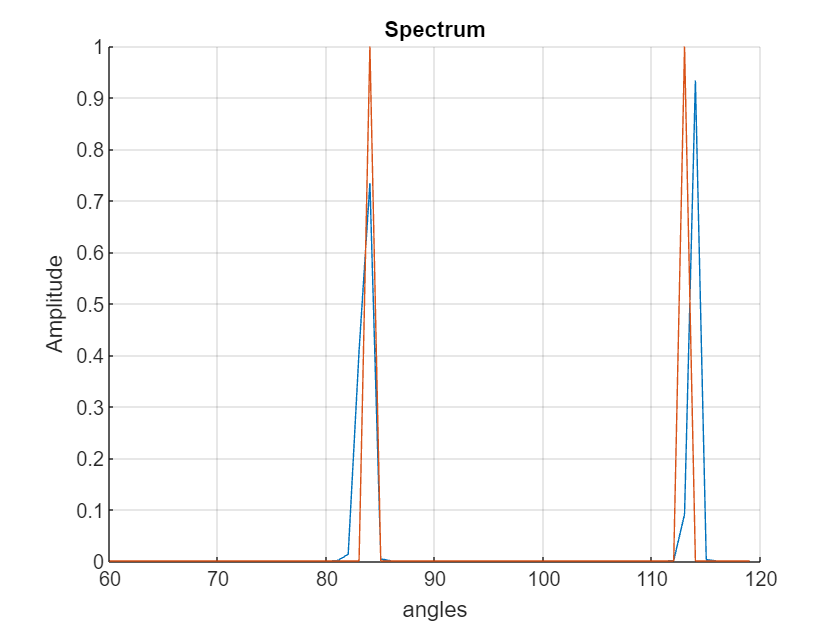

actual doa angles = 84.3013 113.1335


Test(DOA, net);

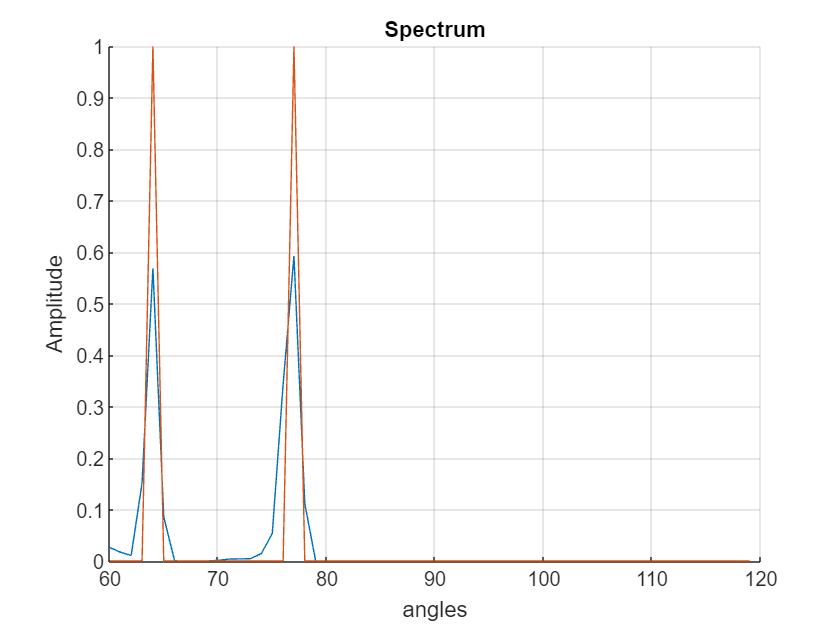

actual doa angles = 63.8243 77.3958


Test(DOA, net);

function Test(DOA, net)
sensor_locations = 0:7; % ULA with 8 sensors
M = length(sensor_locations);
N = sensor_locations(M) + 1;

K = 2;
L = 70;

delta_phi = 1;
phi_min = 60;
phi_max = 119;
angles = phi_min:delta_phi:phi_max;
Q = length(angles);

label = zeros(Q, 1);

doa = (-2 * delta_phi) * ones(1, K);
i = 1;
while true
    temp_angle = phi_min + rand * (phi_max - phi_min);
    temp_array = abs(doa - temp_angle);
    if any(temp_array < delta_phi)
        i = i - 1;
    else
        doa(i) = temp_angle;
    end
    if i == K
        break
    end
    i = i + 1;
end
doa = sort(doa);
rounded_doa = round(doa);
inds = (rounded_doa - phi_min) / delta_phi + 1;
label(inds) = 1;

% original case
A = DOA.Array_Manifold(0.5, sensor_locations, doa);
L = 256; % # of snapshots
Tau = randi(20); % # delay
s_temp = DOA.Source_Generate(1, L + Tau);
s = zeros(K, L);
s(1, :) = s_temp(1:L);
s(2, :) = s_temp(Tau+1:end);
SNR_dB = 0 - rand * 20;
n = DOA.Noise_Generate(SNR_dB, M, L);
y = A * s + n;
R = (1 / L) * (y * y');

r = abs(R(:));
max_r = max(r);

feature(:, :, 1) = (real(R)) / max_r;
feature(:, :, 2) = (imag(R)) / max_r;

pred = predict(net, feature(:, :, 1), feature(:, :, 2));

figure; hold on;
plot(angles, pred);
plot(angles, label);
title('Spectrum');
ylabel('Amplitude');
xlabel('angles');
grid on;

msg = "actual doa angles =";
for i = 1:K
    msg = msg + " " + doa(i);
end
disp(msg);
end